% task2_synth_starter.m
% DIG5111 Assessment Task 2: Subtractive Synthesiser
%
% This script produces a basic subtractive synthesiser output: a sawtooth
% oscillator passed through a static lowpass filter. It runs as-is.
%
% Your task is to build the full synthesis chain:
%   1. Replace the flat envelope with a proper ADSR envelope (write adsr.m)
%   2. Add LFO modulation to the filter cutoff
%   3. Add soft clipping at the output
%   4. Explore the parameter space and document the effect of each parameter
%
% Reference: SynthNotes.pdf (distributed with the assessment materials)
% -------------------------------------------------------------------------

clear; close all;

fs  = 44100;
dur = 2.0;     % note duration (seconds)
f0  = 220;     % fundamental frequency (Hz)

t = (0 : 1/fs : dur - 1/fs);

## =========================================================================

A sawtooth is the standard starting point for subtractive synthesis because it contains every harmonic. See SynthNotes.pdf Section 2.

Manual sawtooth (no Signal Processing Toolbox required):

x_osc = 2 * mod(f0 * t, 1) - 1;

% Alternative waveforms to try:
%   Square (odd harmonics only):  x_osc = sign(sin(2*pi*f0*t));
%   Sine  (fundamental only):     x_osc = sin(2*pi*f0*t);
%
% For FM synthesis, see SynthNotes.pdf Section 3.

## =========================================================================

Currently the envelope is flat. Write an adsr.m function and call it here to give the note an attack, decay, sustain, and release shape.

Your adsr() function should accept: adsr(fs, dur, t_attack, t_decay, s_level, t_release) and return a vector of length round(fs * dur).

See SynthNotes.pdf Section 4 for the segment structure and a suggested implementation approach.

env   = ones(1, length(t));   % flat envelope — replace with adsr() call
x_env = x_osc .* env;

## =========================================================================

Currently the filter is a fixed 2nd-order Butterworth with a static cutoff. This requires the Signal Processing Toolbox (butter).

fc = 1500;                    % cutoff frequency (Hz)
Wn = fc / (fs/2);             % normalised cutoff (0 to 1)
[b_filt, a_filt] = butter(2, Wn, 'low');
x_filt = filter(b_filt, a_filt, x_env);

## =========================================================================

Replace the static filter above with a block-by-block processing loop that redesigns the filter coefficients each block using a time-varying cutoff driven by a low-frequency oscillator (LFO).

The LFO is a sine wave below 20 Hz. Add it to a centre cutoff frequency, scaled by a depth parameter. Clamp the result to stay inside (0, fs/2).

Process the signal in blocks of 256 samples. Carry the filter state (zi) forward between blocks so there are no discontinuities at block boundaries.

See SynthNotes.pdf Section 5 for the block-by-block structure.

## =========================================================================

Add a tanh nonlinearity after the filter. Scale the input signal by a gain factor before tanh and scale back afterwards so the output peaks stay near 1. A gain of 1 is clean; higher values add saturation.

See SynthNotes.pdf Section 6 for the tanh transfer curve and the effect on harmonic content.

## =========================================================================

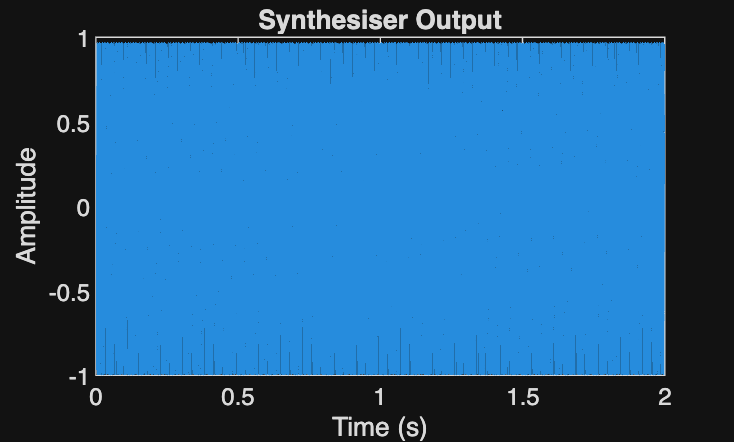

x_out = x_filt / (max(abs(x_filt)) + 1e-12);   % normalise

% Uncomment to listen:
soundsc(x_out, fs);

figure;
plot(t, x_out);
xlabel('Time (s)');  ylabel('Amplitude');
title('Synthesiser Output');


figure;
plot_spectrum(x_out, fs);

plot_spectrum is not found in the current folder or on the MATLAB path, but exists in:
    /Users/premashah/Documents/MATLAB/DIG5111/materials 6

Change the MATLAB current folder or add its folder to the MATLAB path.

title('Synthesiser Output: Magnitude Spectrum');
xlim([0, 5000]);

## =========================================================================

Once the full chain is working, vary one parameter at a time. For each setting, inspect the FFT spectrum and listen to the output. Report what changes and why.

Signal shaping: Waveform, filter cutoff, filter Q, soft clip gain

Modulation and dynamics: LFO rate, LFO depth, attack time, decay time, sustain level, release time

See the parameter tables in the Assessment Task Guide (Section 2) for suggested ranges.